# **Frequency Modulation System**

% FM Code
clear all; clc; clf;
% INSTRUCTIONS

## Modulation

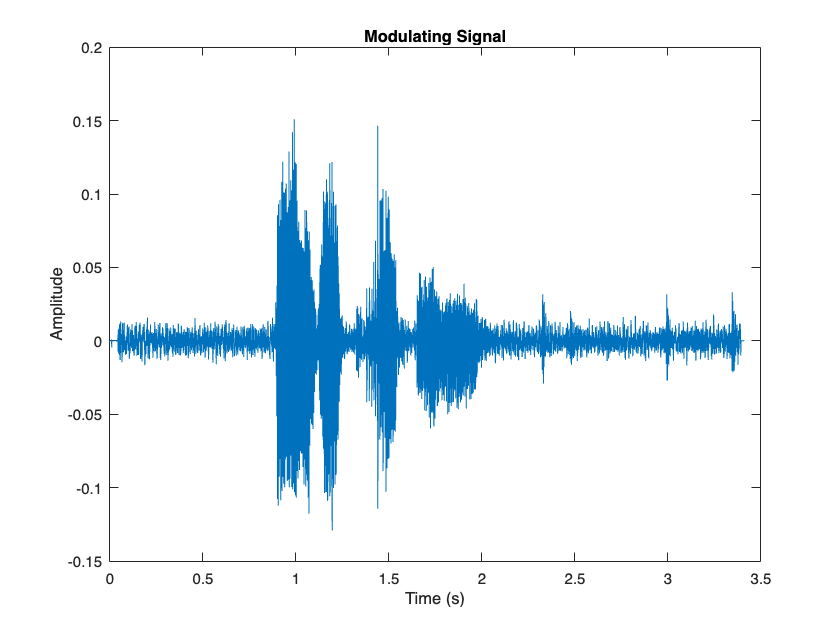

% Step 1: Generate a modulating signal
[y, fm] = audioread('TestAudio.wav');
sound(y,fm)
t = linspace(0, length(y)/fm, length(y));
figure;
plot(t, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('Modulating Signal');

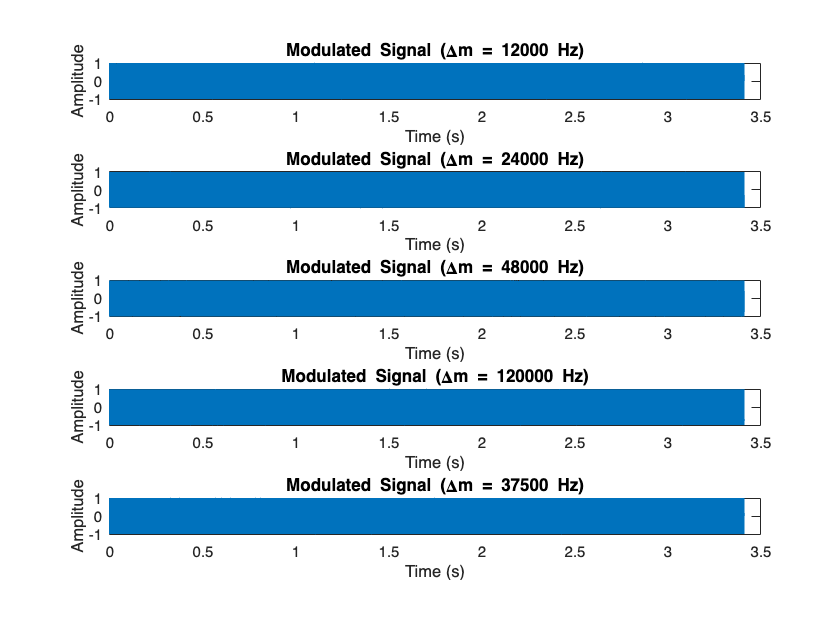

% Step 2: Apply Frequency Modulation

Fc = 10e3; % Carrier frequency
% Fs = 2*Fc;

% Set frequency deviations under test
devf1 = fm/2*0.5;
devf2 = fm/2*1;
devf3 = fm/2*2;
devf4 = fm/2*5;
devf5 = 75000/2;

% Apply frequency modulation
y_fmmod1 = fmmod(y,Fc,fm,devf1);
y_fmmod2 = fmmod(y,Fc,fm,devf2);
y_fmmod3 = fmmod(y,Fc,fm,devf3);
y_fmmod4 = fmmod(y,Fc,fm,devf4);
y_fmmod5 = fmmod(y,Fc,fm,devf5);

figure;
subplot(511)
plot(t, y_fmmod1); xlabel('Time (s)'); ylabel('Amplitude');
title(['Modulated Signal (\Deltam = ' num2str(devf1) ' Hz)']);
subplot(512)
plot(t, y_fmmod2); xlabel('Time (s)'); ylabel('Amplitude');
title(['Modulated Signal (\Deltam = ' num2str(devf2) ' Hz)']);
subplot(513)
plot(t, y_fmmod3); xlabel('Time (s)'); ylabel('Amplitude');
title(['Modulated Signal (\Deltam = ' num2str(devf3) ' Hz)']);
subplot(514)
plot(t, y_fmmod4); xlabel('Time (s)'); ylabel('Amplitude');
title(['Modulated Signal (\Deltam = ' num2str(devf4) ' Hz)']);
subplot(515)
plot(t, y_fmmod5); xlabel('Time (s)'); ylabel('Amplitude');
title(['Modulated Signal (\Deltam = ' num2str(devf5) ' Hz)']);

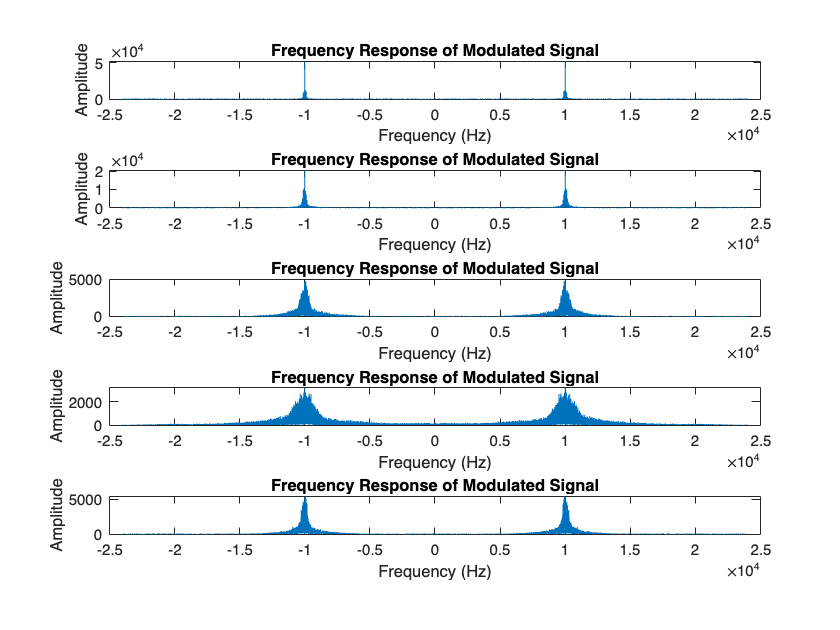

figure;
subplot(511)
fftplot(y_fmmod1,fm)
subplot(512)
fftplot(y_fmmod2,fm)
subplot(513)
fftplot(y_fmmod3,fm)
subplot(514)
fftplot(y_fmmod4,fm)
subplot(515)
fftplot(y_fmmod5,fm)

% Step 3: Amplify the modulated signals
Gfm = 1;
y_afmmod1 = Gfm*y_fmmod1;
y_afmmod2 = Gfm*y_fmmod2;
y_afmmod3 = Gfm*y_fmmod3;
y_afmmod4 = Gfm*y_fmmod4;
y_afmmod5 = Gfm*y_fmmod5;

## During Transmission

% Step 4: Add noise
% Define SNR values (in dB)
snr1 = 0;
snr2 = 2;
snr3 = 5;
snr4 = 10;
snr5 = -2;
snr6 = -5;
snr7 = -10;
snr8 = 70;

% Apply additive white gaussian noise
% For m = 0.5,
y_nafmmod11 = awgn(y_afmmod1,snr1);
y_nafmmod12 = awgn(y_afmmod1,snr2);
y_nafmmod13 = awgn(y_afmmod1,snr3);
y_nafmmod14 = awgn(y_afmmod1,snr4);
y_nafmmod15 = awgn(y_afmmod1,snr5);
y_nafmmod16 = awgn(y_afmmod1,snr6);
y_nafmmod17 = awgn(y_afmmod1,snr7);
y_nafmmod18 = awgn(y_afmmod1,snr8);

% For m = 1,
y_nafmmod21 = awgn(y_afmmod2,snr1);
y_nafmmod22 = awgn(y_afmmod2,snr2);
y_nafmmod23 = awgn(y_afmmod2,snr3);
y_nafmmod24 = awgn(y_afmmod2,snr4);
y_nafmmod25 = awgn(y_afmmod2,snr5);
y_nafmmod26 = awgn(y_afmmod2,snr6);
y_nafmmod27 = awgn(y_afmmod2,snr7);
y_nafmmod28 = awgn(y_afmmod2,snr8);

% For m = 2,
y_nafmmod31 = awgn(y_afmmod3,snr1);
y_nafmmod32 = awgn(y_afmmod3,snr2);
y_nafmmod33 = awgn(y_afmmod3,snr3);
y_nafmmod34 = awgn(y_afmmod3,snr4);
y_nafmmod35 = awgn(y_afmmod3,snr5);
y_nafmmod36 = awgn(y_afmmod3,snr6);
y_nafmmod37 = awgn(y_afmmod3,snr7);
y_nafmmod38 = awgn(y_afmmod3,snr8);

% For m = 5,
y_nafmmod41 = awgn(y_afmmod4,snr1);
y_nafmmod42 = awgn(y_afmmod4,snr2);
y_nafmmod43 = awgn(y_afmmod4,snr3);
y_nafmmod44 = awgn(y_afmmod4,snr4);
y_nafmmod45 = awgn(y_afmmod4,snr5);
y_nafmmod46 = awgn(y_afmmod4,snr6);
y_nafmmod47 = awgn(y_afmmod4,snr7);
y_nafmmod48 = awgn(y_afmmod4,snr8);

% For devf = 75 kHz,
y_nafmmod51 = awgn(y_afmmod5,snr1);
y_nafmmod52 = awgn(y_afmmod5,snr2);
y_nafmmod53 = awgn(y_afmmod5,snr3);
y_nafmmod54 = awgn(y_afmmod5,snr4);
y_nafmmod55 = awgn(y_afmmod5,snr5);
y_nafmmod56 = awgn(y_afmmod5,snr6);
y_nafmmod57 = awgn(y_afmmod5,snr7);
y_nafmmod58 = awgn(y_afmmod5,snr8);

## Demodulation

% Step 5: Demodulate
% For m = 0.5,
y_fmdemod11 = fmdemod(y_nafmmod11,Fc,fm,devf1);
y_fmdemod12 = fmdemod(y_nafmmod12,Fc,fm,devf1);
y_fmdemod13 = fmdemod(y_nafmmod13,Fc,fm,devf1);
y_fmdemod14 = fmdemod(y_nafmmod14,Fc,fm,devf1);
y_fmdemod15 = fmdemod(y_nafmmod15,Fc,fm,devf1);
y_fmdemod16 = fmdemod(y_nafmmod16,Fc,fm,devf1);
y_fmdemod17 = fmdemod(y_nafmmod17,Fc,fm,devf1);
y_fmdemod18 = fmdemod(y_nafmmod18,Fc,fm,devf1);

% For m = 1,
y_fmdemod21 = fmdemod(y_nafmmod21,Fc,fm,devf2);
y_fmdemod22 = fmdemod(y_nafmmod22,Fc,fm,devf2);
y_fmdemod23 = fmdemod(y_nafmmod23,Fc,fm,devf2);
y_fmdemod24 = fmdemod(y_nafmmod24,Fc,fm,devf2);
y_fmdemod25 = fmdemod(y_nafmmod25,Fc,fm,devf2);
y_fmdemod26 = fmdemod(y_nafmmod26,Fc,fm,devf2);
y_fmdemod27 = fmdemod(y_nafmmod27,Fc,fm,devf2);
y_fmdemod28 = fmdemod(y_nafmmod28,Fc,fm,devf1);

% For m = 2,
y_fmdemod31 = fmdemod(y_nafmmod31,Fc,fm,devf3);
y_fmdemod32 = fmdemod(y_nafmmod32,Fc,fm,devf3);
y_fmdemod33 = fmdemod(y_nafmmod33,Fc,fm,devf3);
y_fmdemod34 = fmdemod(y_nafmmod34,Fc,fm,devf3);
y_fmdemod35 = fmdemod(y_nafmmod35,Fc,fm,devf3);
y_fmdemod36 = fmdemod(y_nafmmod36,Fc,fm,devf3);
y_fmdemod37 = fmdemod(y_nafmmod37,Fc,fm,devf3);
y_fmdemod38 = fmdemod(y_nafmmod38,Fc,fm,devf3);

% For m = 5,
y_fmdemod41 = fmdemod(y_nafmmod41,Fc,fm,devf4);
y_fmdemod42 = fmdemod(y_nafmmod42,Fc,fm,devf4);
y_fmdemod43 = fmdemod(y_nafmmod43,Fc,fm,devf4);
y_fmdemod44 = fmdemod(y_nafmmod44,Fc,fm,devf4);
y_fmdemod45 = fmdemod(y_nafmmod45,Fc,fm,devf4);
y_fmdemod46 = fmdemod(y_nafmmod46,Fc,fm,devf4);
y_fmdemod47 = fmdemod(y_nafmmod47,Fc,fm,devf4);
y_fmdemod48 = fmdemod(y_nafmmod48,Fc,fm,devf4);

% For devf = 75 kHz,
y_fmdemod51 = fmdemod(y_nafmmod51,Fc,fm,devf5);
y_fmdemod52 = fmdemod(y_nafmmod52,Fc,fm,devf5);
y_fmdemod53 = fmdemod(y_nafmmod53,Fc,fm,devf5);
y_fmdemod54 = fmdemod(y_nafmmod54,Fc,fm,devf5);
y_fmdemod55 = fmdemod(y_nafmmod55,Fc,fm,devf5);
y_fmdemod56 = fmdemod(y_nafmmod56,Fc,fm,devf5);
y_fmdemod57 = fmdemod(y_nafmmod57,Fc,fm,devf5);
y_fmdemod58 = fmdemod(y_nafmmod58,Fc,fm,devf5);

% Design filter
n = 2;
Rs = 20;
Ws = 0.075;
[b,a] = cheby2(n,Rs,Ws);

% Apply filter
% For m = 0.5,
y_ffmdemod11 = filter(b,a,y_fmdemod11);
y_ffmdemod12 = filter(b,a,y_fmdemod12);
y_ffmdemod13 = filter(b,a,y_fmdemod13);
y_ffmdemod14 = filter(b,a,y_fmdemod14);
y_ffmdemod15 = filter(b,a,y_fmdemod15);
y_ffmdemod16 = filter(b,a,y_fmdemod16);
y_ffmdemod17 = filter(b,a,y_fmdemod17);
y_ffmdemod18 = filter(b,a,y_fmdemod18);

% For m = 1,
y_ffmdemod21 = filter(b,a,y_fmdemod21);
y_ffmdemod22 = filter(b,a,y_fmdemod22);
y_ffmdemod23 = filter(b,a,y_fmdemod23);
y_ffmdemod24 = filter(b,a,y_fmdemod24);
y_ffmdemod25 = filter(b,a,y_fmdemod25);
y_ffmdemod26 = filter(b,a,y_fmdemod26);
y_ffmdemod27 = filter(b,a,y_fmdemod27);
y_ffmdemod28 = filter(b,a,y_fmdemod28);

% For m = 2,
y_ffmdemod31 = filter(b,a,y_fmdemod31);
y_ffmdemod32 = filter(b,a,y_fmdemod32);
y_ffmdemod33 = filter(b,a,y_fmdemod33);
y_ffmdemod34 = filter(b,a,y_fmdemod34);
y_ffmdemod35 = filter(b,a,y_fmdemod35);
y_ffmdemod36 = filter(b,a,y_fmdemod36);
y_ffmdemod37 = filter(b,a,y_fmdemod37);
y_ffmdemod38 = filter(b,a,y_fmdemod38);

% For m = 5,
y_ffmdemod41 = filter(b,a,y_fmdemod41);
y_ffmdemod42 = filter(b,a,y_fmdemod42);
y_ffmdemod43 = filter(b,a,y_fmdemod43);
y_ffmdemod44 = filter(b,a,y_fmdemod44);
y_ffmdemod45 = filter(b,a,y_fmdemod45);
y_ffmdemod46 = filter(b,a,y_fmdemod46);
y_ffmdemod47 = filter(b,a,y_fmdemod47);
y_ffmdemod48 = filter(b,a,y_fmdemod48);

% For devf = 75 kHz,
y_ffmdemod51 = filter(b,a,y_fmdemod51);
y_ffmdemod52 = filter(b,a,y_fmdemod52);
y_ffmdemod53 = filter(b,a,y_fmdemod53);
y_ffmdemod54 = filter(b,a,y_fmdemod54);
y_ffmdemod55 = filter(b,a,y_fmdemod55);
y_ffmdemod56 = filter(b,a,y_fmdemod56);
y_ffmdemod57 = filter(b,a,y_fmdemod57);
y_ffmdemod58 = filter(b,a,y_fmdemod58);



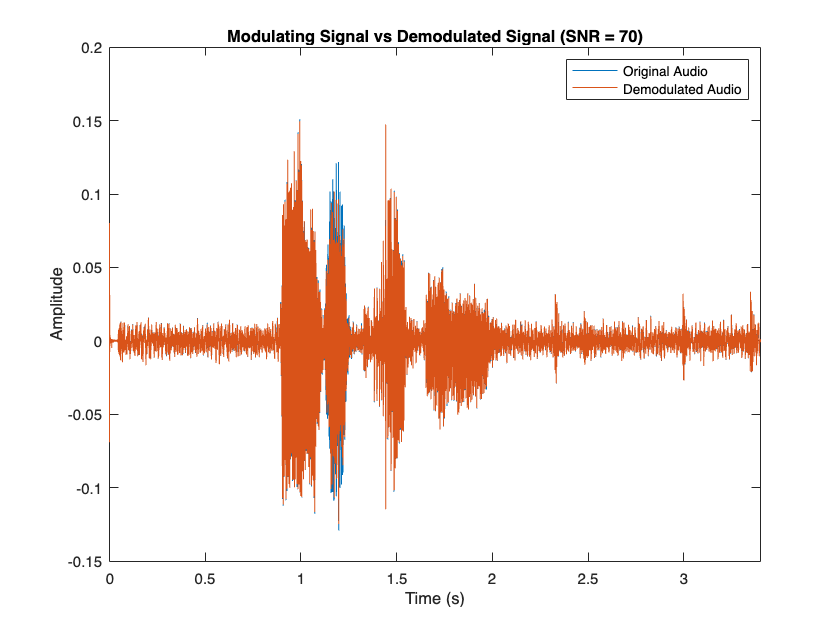

% Write audio signals
sound(y_fmdemod18,fm)
figure;
plot(t,y);
hold on
plot(t,y_fmdemod18);
xlim([0 3.4])
legend('Original Audio','Demodulated Audio')
xlabel('Time (s)');
ylabel('Amplitude');
title('Modulating Signal vs Demodulated Signal (SNR = 70)');

function fftplot(signal,Fs)
    [N,~] = size(signal);
    t = -Fs/2:Fs/(N-1):Fs/2;
    signalfreq = fftshift(fft(signal));
    plot(t,abs(signalfreq)); xlabel("Frequency (Hz)"); ylabel("Amplitude");
    title("Frequency Response of Modulated Signal")
end